# Motor Data Processing 

## Thrust Threshold Estimation

% Set-up 
Payload = 25; % lb
BatteryW = 3; % kg 
MotorW = 250; % g
WeightFS = 1.2; % Dimensionless 

% Conversion
Payload = Payload*0.453592; % lb -> kg conversion
MotorW = MotorW/1000; % g -> kg conversion

%% DownForce
TotalDownForce = (Payload+MotorW+BatteryW)*9.8*1.2;
MAXThrustEst = TotalDownForce*2 ;
Thrust_Threshold = MAXThrustEst/8;



## house keeping

clc; clear; close all;


## Motors

% Load Data
Motor_Names = ["KDE3520XF-400","KDE4215XF-465","KDE5215XF-330","KDE7215XF-135" ...
    "MN501-S KV240","MN501-S KV300","MN501-S KV360","U10 II KV100","U5 KV400","U7-V2.0 KV280","U8 II Pro","U8 Lite L KV95"];


## Motor Thrust vs. Prop Size @ 50% Throttle

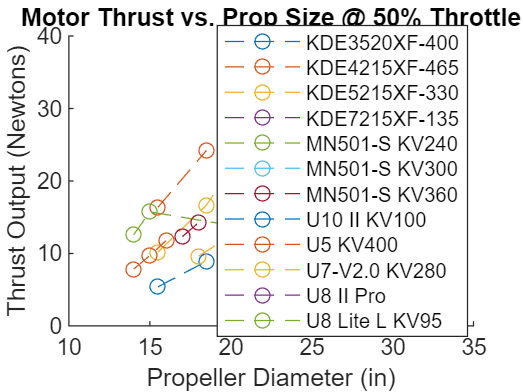

for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    PropD = Motor_Matrix(:,1);
    Thrust = Motor_Matrix(:,2)*0.009807; %convert Grams to Newtons
    figure(1)
    hold on
    title('Motor Thrust vs. Prop Size @ 50% Throttle')
    xlabel('Propeller Diameter (in)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

## Motor Thrust vs. Prop Size @ 100% Throttle

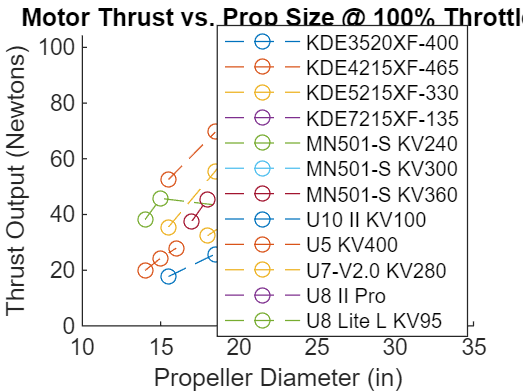

for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(2)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,1);
    Max_thrust(n) = max(Thrust);
    
    % Thrust Threshold Calc
    Payload = 35*0.453592;              %kilograms
    Est_Battery_W = 3;                  %kilograms
    MotorW = Motor_Matrix(end,9)/1000;  %kilograms
    TotalDownForce = (Payload+MotorW+Est_Battery_W)*9.8*1.2; %Newtons
    MAXThrustEst = TotalDownForce*2; 
    Thrust_Threshold = MAXThrustEst/8;                       %Newtons


    if (Max_thrust(n) > Thrust_Threshold)
        Acceptable_Motors(n) = Motor_Names(n);
    end

    hold on
    title('Motor Thrust vs. Prop Size @ 100% Throttle')
    xlabel('Propeller Diameter (in)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

Acceptable_Motors = rmmissing(Acceptable_Motors);

## current draw vs thrust

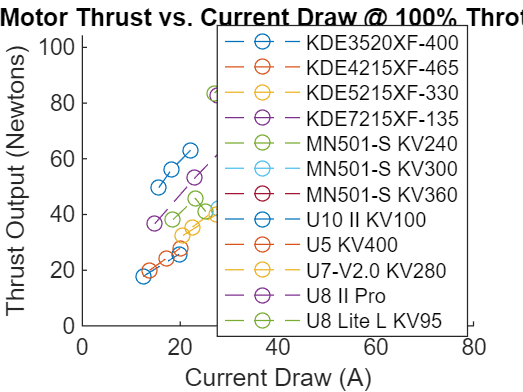

for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(3)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,5);
    hold on
    title('Motor Thrust vs. Current Draw @ 100% Throttle')
    xlabel('Current Draw (A)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

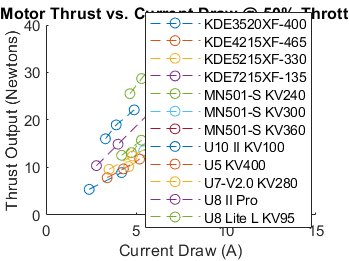


for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(4)
    Thrust = Motor_Matrix(:,2)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,4);
    hold on
    title('Motor Thrust vs. Current Draw @ 50% Throttle')
    xlabel('Current Draw (A)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

## Thrust Vs. Power

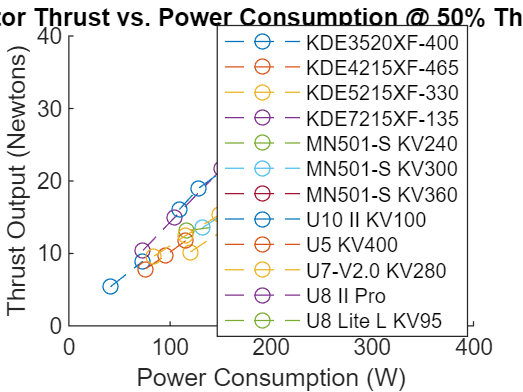

for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(5)
    Thrust = Motor_Matrix(:,2)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,6);
    hold on
    title('Motor Thrust vs. Power Consumption @ 50% Throttle')
    xlabel('Power Consumption (W)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")

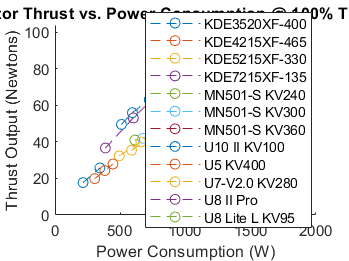


for n = 1:length(Motor_Names)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    figure(6)
    Thrust = Motor_Matrix(:,3)*0.009807; % convert grams to Newtons
    PropD = Motor_Matrix(:,7);
    hold on
    title('Motor Thrust vs. Power Consumption @ 100% Throttle')
    xlabel('Power Consumption (W)')
    ylabel(['Thrust Output (Newtons)'])
    plot(PropD, Thrust,'--o')
end
legend(Motor_Names,'Location',"best")
hold off

## Thrust to weight ratio

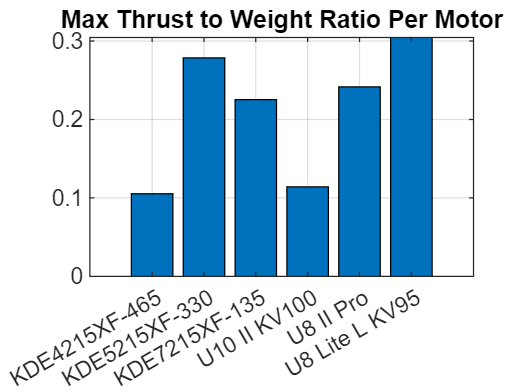

for n = 1:length(Acceptable_Motors)
    Motor_Matrix = csvread('Motor Data - '+ Motor_Names(n) + '.csv',1,0);
    Thrust = Motor_Matrix(end,3)*0.009807; % convert grams to Newtons
    T2W(n) = Thrust / Motor_Matrix(end,9);
end
figure(7)
title('Max Thrust to Weight Ratio Per Motor')
grid on

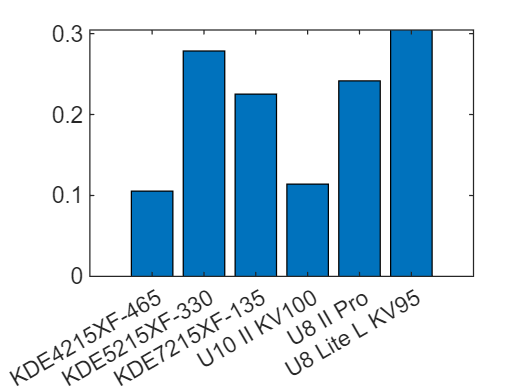

bar(T2W)
xticklabels(Acceptable_Motors)